clear
close all
clc

T_A = 4e-3;
f_A = 1/T_A;


data = transpose(load("uC_data.mat").dataOut(:,2));
%data = load("gabriel_ekg.mat").data;
BUFFERSIZE = length(data);
t = linspace(0,30,BUFFERSIZE);

peakDetected = false;

figure
plot(t, data)
hold

Current plot held


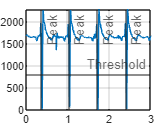

i = 95

lastTime = 0.3761

i = 260

lastTime = 1.0361

i = 431

lastTime = 1.7202

i = 602

lastTime = 2.4043

i = 772

lastTime = 3.0844

i = 949

lastTime = 3.7925

i = 1122

lastTime = 4.4846

i = 1297

lastTime = 5.1847

i = 1470

lastTime = 5.8768

i = 1644

lastTime = 6.5729

i = 1821

lastTime = 7.2810

i = 2001

lastTime = 8.0011

i = 2170

lastTime = 8.6772

i = 2342

lastTime = 9.3652

i = 2517

lastTime = 10.0653

i = 2698

lastTime = 10.7894

i = 2867

lastTime = 11.4655

i = 3041

lastTime = 12.1616

i = 3227

lastTime = 12.9057

i = 3420

lastTime = 13.6778

i = 3622

lastTime = 14.4859

i = 3818

lastTime = 15.2700

i = 3996

lastTime = 15.9821

i = 4169

lastTime = 16.6742

i = 4339

lastTime = 17.3543

i = 4508

lastTime = 18.0304

i = 4677

lastTime = 18.7065

i = 4841

lastTime = 19.3626

i = 5003

lastTime = 20.0107

i = 5163

lastTime = 20.6508

i = 5322

lastTime = 21.2868

i = 5484

lastTime = 21.9349

i = 5651

lastTime = 22.6030

i = 5823

lastTime = 23.2911

i = 5997

lastTime = 23.9872

i = 6167

lastTime = 24.6673

i = 6339

lastTime = 25.3554

i = 6508

lastTime = 26.0315

i = 6672

lastTime = 26.6876

i = 6837

lastTime = 27.3476

i = 7005

lastTime = 28.0197

i = 7174

lastTime = 28.6958

i = 7345

lastTime = 29.3799

xlim([0 3])
yline(800,'-' ,'Threshold')
grid
n=1;
heartTime(1) = 0;
lastTime = 0;
for i=4:BUFFERSIZE
    if data(i) <  750
        if(data(i) < data(i-1))
            if peakDetected == false
                if (t(i) - lastTime) > 0.2
                    i
                    lastTime = t(i)
                    heartTime(n) = t(i);
                    xline(t(i), '-','Peak')
                    peakDetected = true;
                    if(n>1)
                        heartRate = heartTime(n) - heartTime(n-1);
                    end
                    n = n+1;
                end
            end
        elseif data(i) > data(i-1)
            peakDetected = false;
        end
    end
end